# How to use MATLAB B-FRET code package

## 1. Preparing data

All FRET data analyzed by the B-FRET algorithm written in MATLAB needs to be stored in a MAT file (.mat file).  This MAT file should contain a structure array called `all_data` that stores all the following information: observables (i.e., the time series of fluoresence signals,$I_{\mathrm{AA}\;} ,I_{\mathrm{DD}} ,\;$and $I_{\mathrm{DA}}$), time points for each measurement ($t_{1:N_D }^D$ and $t_{1:N_A }^A$), imaging-sytem parameters ($a,d$, and $G$), and the standard deviations of measurement noise at each time point for each obsevable ($\sigma {\;}_{\textrm{AA}\;}$, $\sigma {\;}_{\textrm{DD}\;}$, and $\sigma {\;}_{DA\;}$).

Below, we look at how these pieces of information are stored in one of the example data sets.  

We first load a set of synthetic FRET data that exhibit oscillatory FRET dynamics (`data_sinusoids.mat`; See Supplementary information of the B-FRET paper for how this and other data sets were generated). Before executing the following lines, make sure your current folder is right above the `sample_code` folder.  

cd './sample_code';
dir0 = pwd; % remember the current folder for later use 
cd './data/' % move to the directory where sample data are stored
load 'data_sinusoids.mat' % load the data file

This data set contains observables from 5 samples in `all_data.IAA`, `all_data.IDD`, and `all_data.IDA`. The time-series data are organized into 5 x N matrices, where N (= 1201) is the length of the time series. We plot the observables for the first sample. Note that the length of $I_{\mathrm{AA}\;}$ and that of $I_{\mathrm{DD}}$, and $I_{\mathrm{D}A} \;$happen to be the same in this data set, but they don't have to be the same in general. 

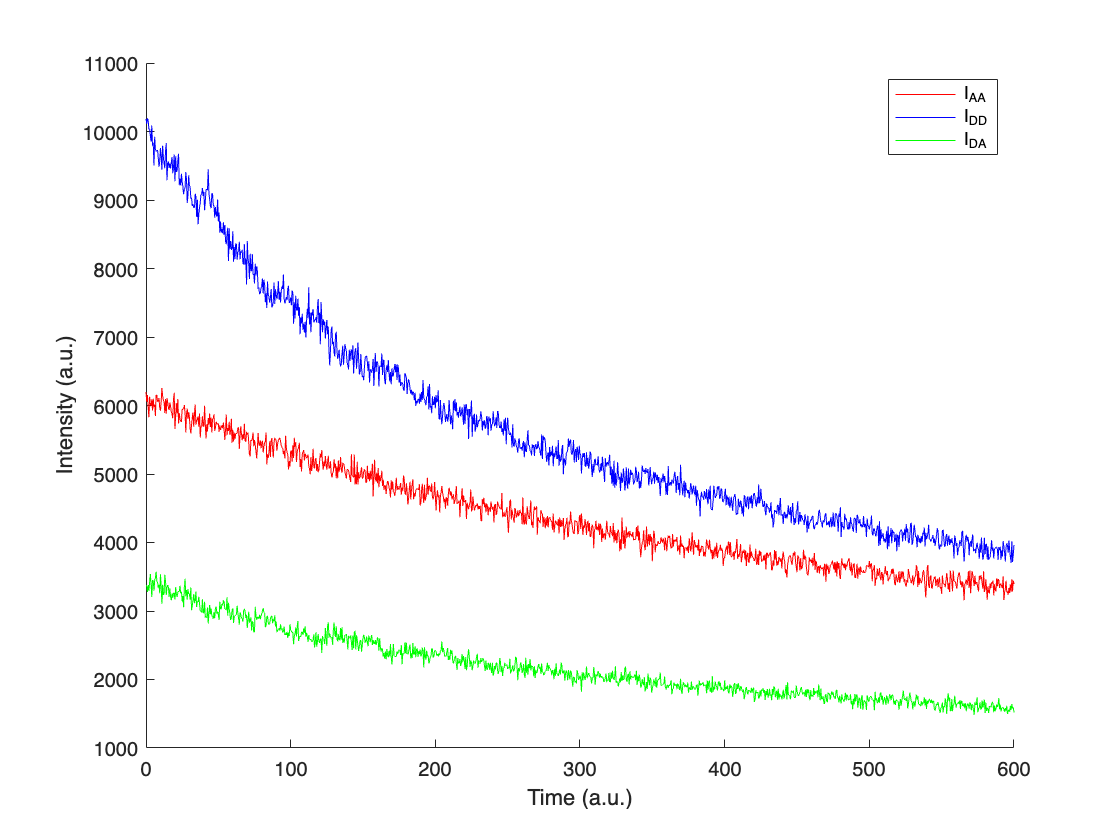

figure,hold on;
l1 = plot(all_data.tAA, all_data.IAA(1,:),'r-');
l2 = plot(all_data.tDD, all_data.IDD(1,:),'b-');
l3 = plot(all_data.tDD, all_data.IDA(1,:),'g-');
legend([l1,l2,l3],'I_{AA}','I_{DD}','I_{DA}');
xlabel('Time (a.u.)')
ylabel('Intensity (a.u.)')

This synthetic data emulates photophysical processes including photobleahcing and measurement noise, and so the intensities decrease over time and are noisy. All of the five data sets are identical in that they were generated using the same set of parameters and the dynamics of $\chi \left(t\right)=E_{\max } \left\lbrack {\mathrm{DA}}_{\mathrm{total}} \right\rbrack \left(t\right)$; however, the realizations of the measurement noise are different among the five data sets, and so the outputs of the B-FRET algorithm will be different too. 

Three imaging-system (or crosstalk) parameters determined by independent measurements are stored in a structure array `crstlk`:

all_data.crstlk.a % A value of a

ans = 0.3500

all_data.crstlk.d % A value of d

ans = 0.0900

all_data.crstlk.G % A value of G

ans = 0.5000

`all_data` also contains the standard deviation of the measurement noise of each time series at each time point in `all_data.IAA_noise_sd`, `all_data.IDD_noise_sd`, and `all_data.IDA_noise_sd`. Note that the standard deviation of the measurement noise changes in time in general because the magnitude of photon shot noise, the major source of noise in FRET measurements, decreases as fluoresence intensities decrease due to photobleaching. 

We plot the standard deviation of measurement noise for the first sample:

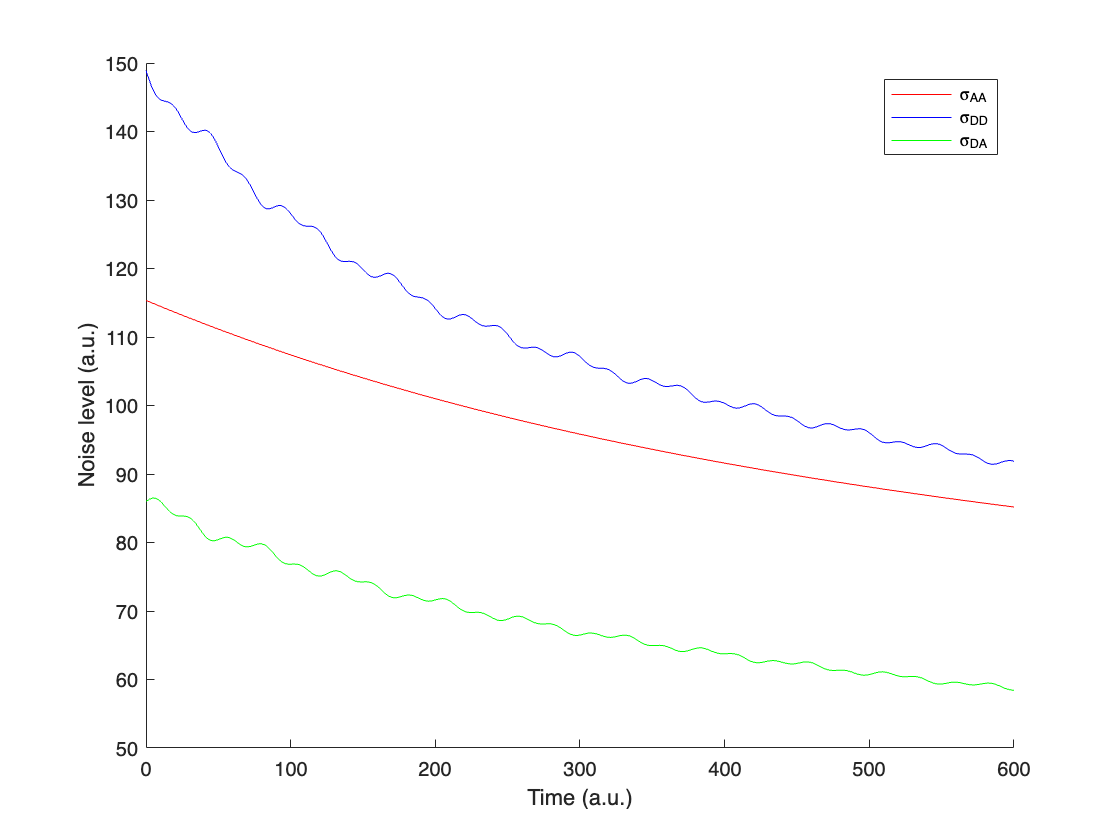

figure,hold on;
l1 = plot(all_data.tAA, all_data.IAA_noise_sd(1,:),'r-');
l2 = plot(all_data.tDD, all_data.IDD_noise_sd(1,:),'b-');
l3 = plot(all_data.tDD, all_data.IDA_noise_sd(1,:),'g-');
legend([l1,l2,l3],'\sigma_{AA}','\sigma_{DD}','\sigma_{DA}');
xlabel('Time (a.u.)')
ylabel('Noise level (a.u.)')

The following fields in `all_data` are also available for the sample data sets, but they are not used by the B-FRET algorithm. We stored these in it becaue they are useful in evaluating the performance of the algorithm. 

all_data.chi; %1 x 1201 vector storing the time series of true values of chi
all_data.E; % 1 x 1201 vector storing the time series of true values of FRET index (= Emax*chi/DT)
all_data.data_params;% Structure containing all the parameter values (See Supplementary Information for the explanation of each parameter)
all_data.IAA_bar;% Expected value of IAA, i.e., zero-noise version of IAA
all_data.IDD_bar;% Expected value of IDD, i.e., zero-noise version of IDD
all_data.IDA_bar;% % Expected value of IDA, i.e., zero-noise version of IDA

## 2. Defining analysis parameters and model functions

The behavior of the B-FRET alrorithm depnds on several analysis parameters and model functions. They are defined in `define_analysis_params.m` and `define_model_functions.m`,  respectively. These two files needs to be edited accordingly and stored in the "root directory" of an analysis (defined as 'dir_info.root_dir' as shown in the next section) in which analysis results (i.e., the outputs of the B-FRET code) are stored. The sample code folder contains examples of these files in the folder `sample_code/definition_files_examples`. So, we first make the "root directory" (`analysis_results`). Then, we copy the files in the "root directory". 

cd(dir0)
mkdir ./analysis_results % making the "root directory"
cd ./definition_files_examples/ % moving to the folder with examples of "definition files"
copyfile define_analysis_params.m  ../analysis_results % copying define_analysis_params.m to the "root directory" 
copyfile define_model_functions.m ../analysis_results % copying define_model_functions.m to the "root directory" 

### **2.1. Instructions on how to set the parameters in **`define_analysis_params.m`

First, you define whether to use a Gaussian process noise or a Non-Gaussian process noise (`anl_params.process_noise`). For a Non-Gaussian process noise, some integrals with respect to $\chi \;$over an infinite interval (i.e.,$\int_{-\infty \;}^{\infty \;} f\left(\chi \;\right)d\chi \;$) have to be evaluated numerically. For this purpose, the infinite interval needs to be replaced with a sufficiently large but finite interval (since a computer cannot deal with an infinite interval) and the finite interval needs to be divided into subintervals (since a computer cannot deal with continuous functions). The width of the integral interval is set by `anl_params.chi_interval_width` in the unit of the range in which roughly estimated $\chi$ changes. Typically, `~10` (i.e., the integration interval is 10 fold wider than the range in which naively-estimated $\chi$ varies) is sufficient. The number of subintervals within the integration interval is set by `anl_params.chi_num_of_subintervals`. The larger this number gets, the more precise the integration becomes but, computationally, the more costly it gets . To get a sence of how large this number should be, one can look at the plots of the integrands as functions of $\chi$, which the B-FRET algorithm automatically generates when a Non-Gaussian process noise is used and the plots are saved as `approximated_distrs_examples.fig` -- if the integrands are sufficiently smooth then the inregrands will be well approximated.Typically, ~400 subintervals are sufficient.

As the default Non-Gaussian process noise, we use the Student's t-distribution, which is defined in `define_model_functions.m` and has a parameter called the degree of freedom, $\nu \;$. In estimating $\nu$ via the B-FRET algorithm, we need the prior distribution of $\nu$, $p\left(\nu \right)$. We use a log-normal distribution for this prior, and `anl_params.nu_ini` gives the mode of $p\left(\nu \right)$ and `anl_params.nu_FC` gives the standard deviation of $p\left(\log \left(\nu \;\right)\right)$ as can be seen in `define_model_functions.m`. 

Second, irrespective of whether you use a Gaussian distribution or a Student's t distribution as process noise, you need to define the prior distribution for $\sigma {\;}_{\chi \;}$, $p\left(\sigma {\;}_{\chi \;} \right)$. $\sigma {\;}_{\chi \;}$defines the standard deviation of the Gaussian distribution for the Gaussian-process-noise case and the scale parameter of the Studnet's t-distribution for the Non-Gaussian-process-noise case. `anl_params.sigma_chi_ini` defines the mode of the prior distribution and `anl_params.sigma_chi_ini` defines the standard deviation of $p\left(\log \left(\sigma_{\chi \;\;} \right)\right)$ as can be seen in `define_model_functions.m`. 

Third, if you choose *not* to do a Markov chain Monte Carlo (MCMC) sampling from the posterior distribution of model parameters (i.e., `anl_params.do_MCMC = 0`), B-FRET approximates the posterior distribution by a Gaussian distribution (Laplace approximation) and draw samples from the Gaussian distribution. `anl_params.Laplace_nsamples` sets the number of samples drawn from the distribution. Usually about `1000` is sufficient. 

Fourth, if you choose to do a MCMC sampling from the posterior distribution of the model parameters (anl_params.do_MCMC = 1), you need to define parameters related to the MCMC sampling procedure. `anl_params.num_of_workers` sets the number of CPUs used for parallel computing (`parfor` in Matlab). The rest are the parameters fed into the MATLAB function `slicesample, which implements the `slicesampling algorithm.

### **2.2. Instructions on how to set the parameters in **`define_model_functions.m`

First, you have to define the functional forms of $f_D$ and $f_{A\;}$ with unknown parameters. These functions are fitted to data to obtain initial rough estimations of the parameters.The initial parameter values (e.g., `mdl_fun.f_D.p_ini`) and lower and upper bounds of the parameter values used in the fitting procedure (e.g., `mdl_fun.f_A.p_lb` and `mdl_fun.f_D.p_ub`) are defined. Also, the name of the parameters are defined (e.g., `mdl_fun.f_D.p_name`) and these names should be used as field names when you define the prior distributions in the structure `mdl_fun.prior0` within the same file.

Second, if you choose to use a Non-Gaussian process noise, you need to define the functional form and the names of the prameters. In the sample code, the Student's t-distribution is defined in `mdl_fun.Q_tilde.fun.`  

Finally, you define the prior distribution of each parameter. For example, the line 

`mdl_fun.prior0.tau_D1 = @(x,p_ini) lognpdf(x, mu(p_ini),sigma)`;

defines the prior distribution of `tau_D1` as the log-normal distribution with parameter values of `mu(p_ini)` and `sigma`. Note that, although `sigma` is defined in the same file, `mu(p_ini)` is a function of an initial estimation of the parameter `p_ini` and this is not given within the file. Instead, `p_ini` is given by the B-FRET algorithm in a way that is dependent on the data (see Supplementary Information for more details about how are these initial estimations are given). 

## 3. Executing the B-FRET algorithm 

First, you need to add the folder, `sample_code/B-FRET_functions`, to the search path. This folder contains all the functions used in the B-FRET algorithm.  

cd(dir0) 
addpath './B-FRET_functions' 

We go to the "root directory" in which you saved the two definition files (define_analysis_params.m and define_model_functions.m).

cd './analysis_results'

Then, you organize some directory information into a structure `dir_info.`

dir_info.root_dir = pwd;% Results are saved under this folder
dir_info.sub_dir_base_name = 'data_';% The results from each sample is saved under the folder named, e.g., 'data_1'. 

Finally, execute the B-FRET algorithm.

analyze_FRET_data(all_data,dir_info)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping cr

Once you have analyzed all the data, you can removed the folder, `sample_code/B-FRET_functions`, from the search path. 

cd(dir0)
rmpath './B-FRET_functions'

Note that B-FRET skips analyzing *i*-th data (e.g., those stored in *i*-th row in `all_data.IAA`, `all_data.IDD`, and `all_data.IDA`) if there is a corresponding folder (e.g., data_1) in the "root directory". So, you need to delete the files if you want to reanalyze the data. 

## 4. Interpreting B-FRET results: sanity check figures

The B-FRET algorithm executed above genenates numerical results saved in `Bayes_FRET_result.mat` and several sanity check plots in the folder named `sanity_check `for each data set. First we look at the sanity check plots.

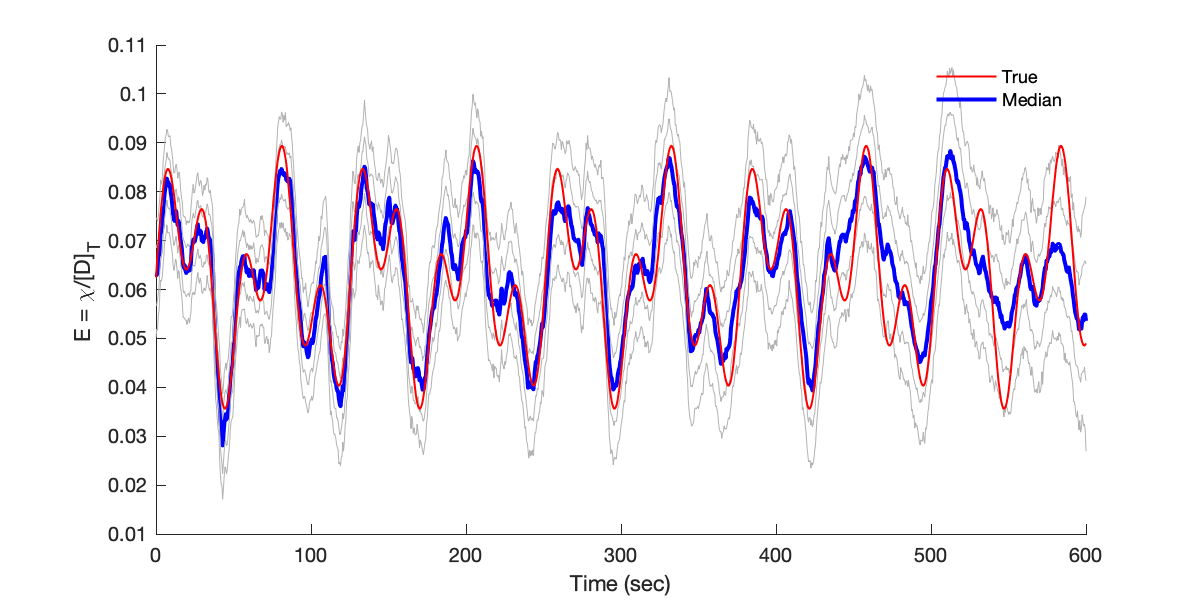

cd(dir0)
cd ./analysis_results/data_1/sanity_check/
openfig('./E.fig');
set(gcf,'Visible','on')

This figure shows true values of $E=\frac{\chi \;}{\left\lbrack D_{\textrm{total}} \right\rbrack }$ in red, the median of the posterior distribution of $E$ in blue and 2.27, 15.83, 84.13, and 97.73 percentiles (corresponding to one and two standard deviations of a Gaussian distribution) are shown in grey. 

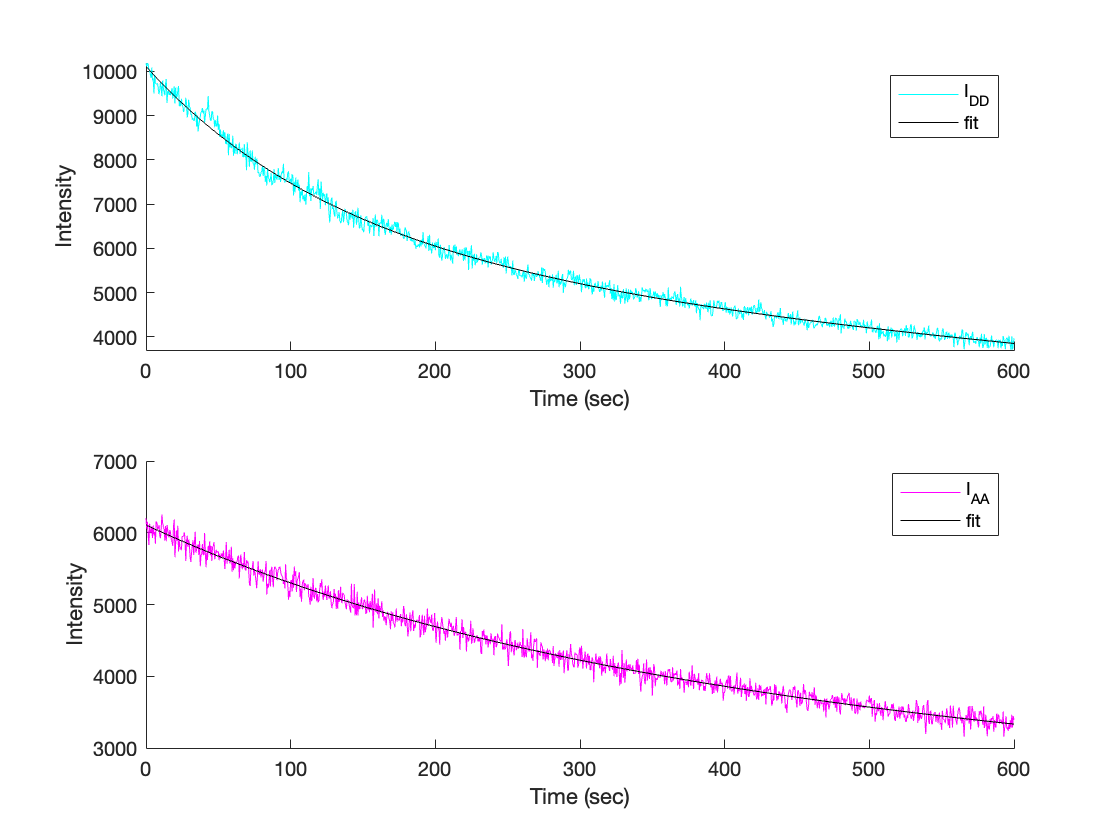

openfig('./initial_est_bleach_trend.fig');
set(gcf,'Visible','on')

This top panel shows $I_{\mathrm{DD}}$ and $f_D$ fitted to $I_{\mathrm{DD}}$ (after approprate rescaling of  $f_D$) to roughly estimate the parameters of $f_D$. The bottom panel shows $I_{\mathrm{AA}}$ and $f_A$ fitted to $I_{\mathrm{AA}}$ (after approprate rescaling of  $f_A$) to roughly estimate the parameters of $f_A$. The estimated parameters are used as an inital value for the optimization process conducted in the B-FRET algorithm. Therefore, the fitting results need to be reasonably good to successfully execute the B-FRET algorithm.

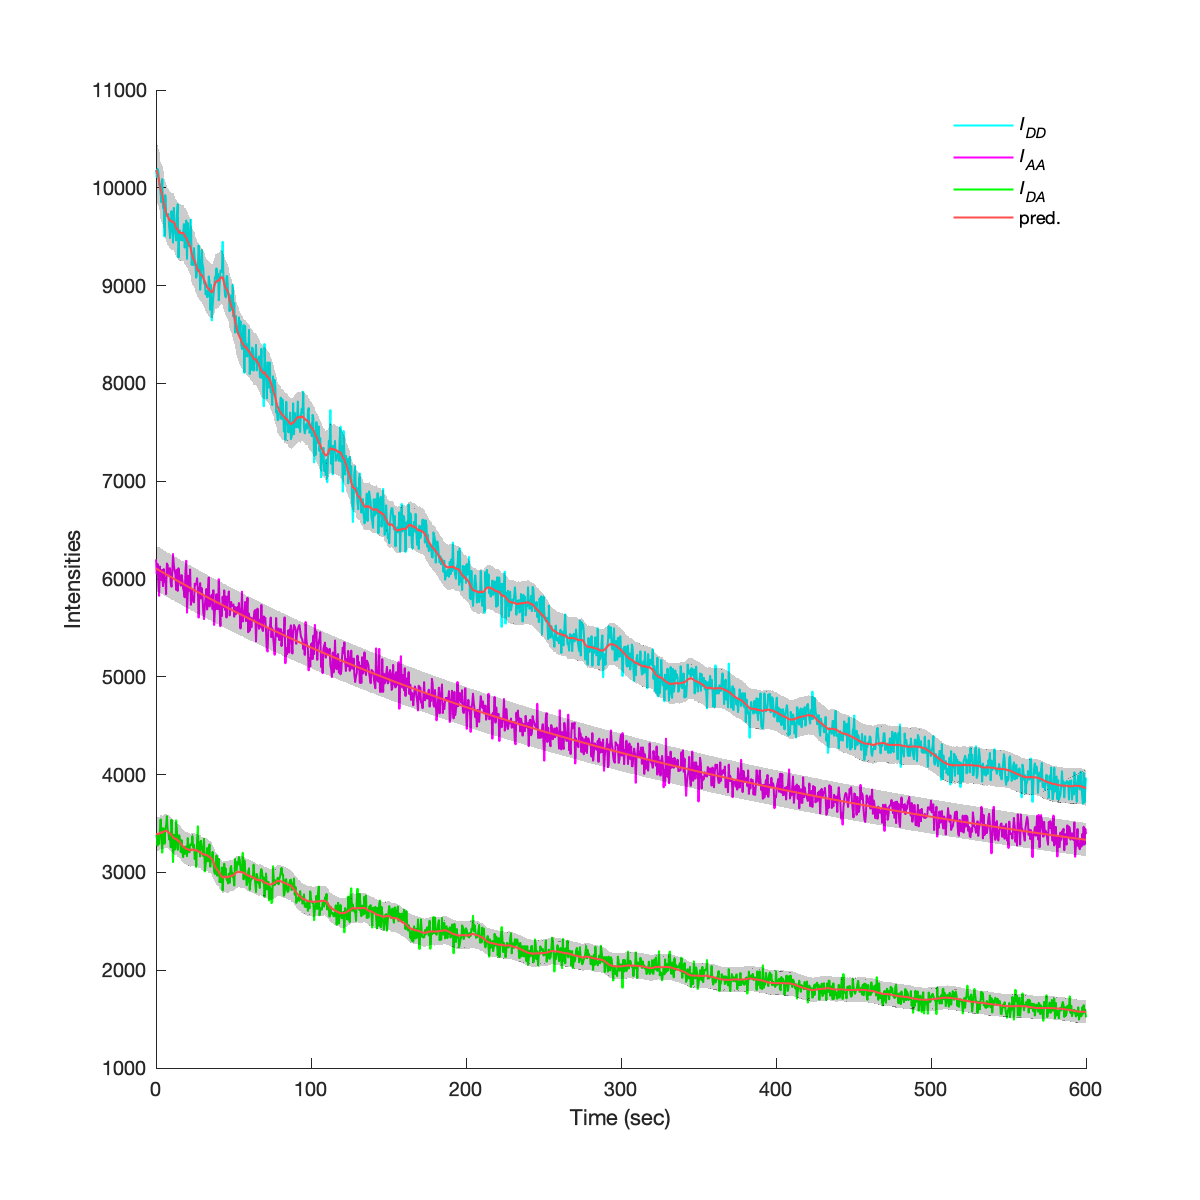

openfig('./observables.fig');
set(gcf,'Visible','on')

This plot shows raw observable data $I_{\textrm{AA}}$, $I_{\textrm{DA}}$, and $I_{\textrm{DD}}$in magenta, green and blue respectively, and the prediction of those observables by the learned model (the median of the smoothing distribution in red and two standard deviations as grey shade). If the prediction is off from the observables, it suggests that there ia a processe (or processes) in the system that is not taken into consideration in the photophysical model.    

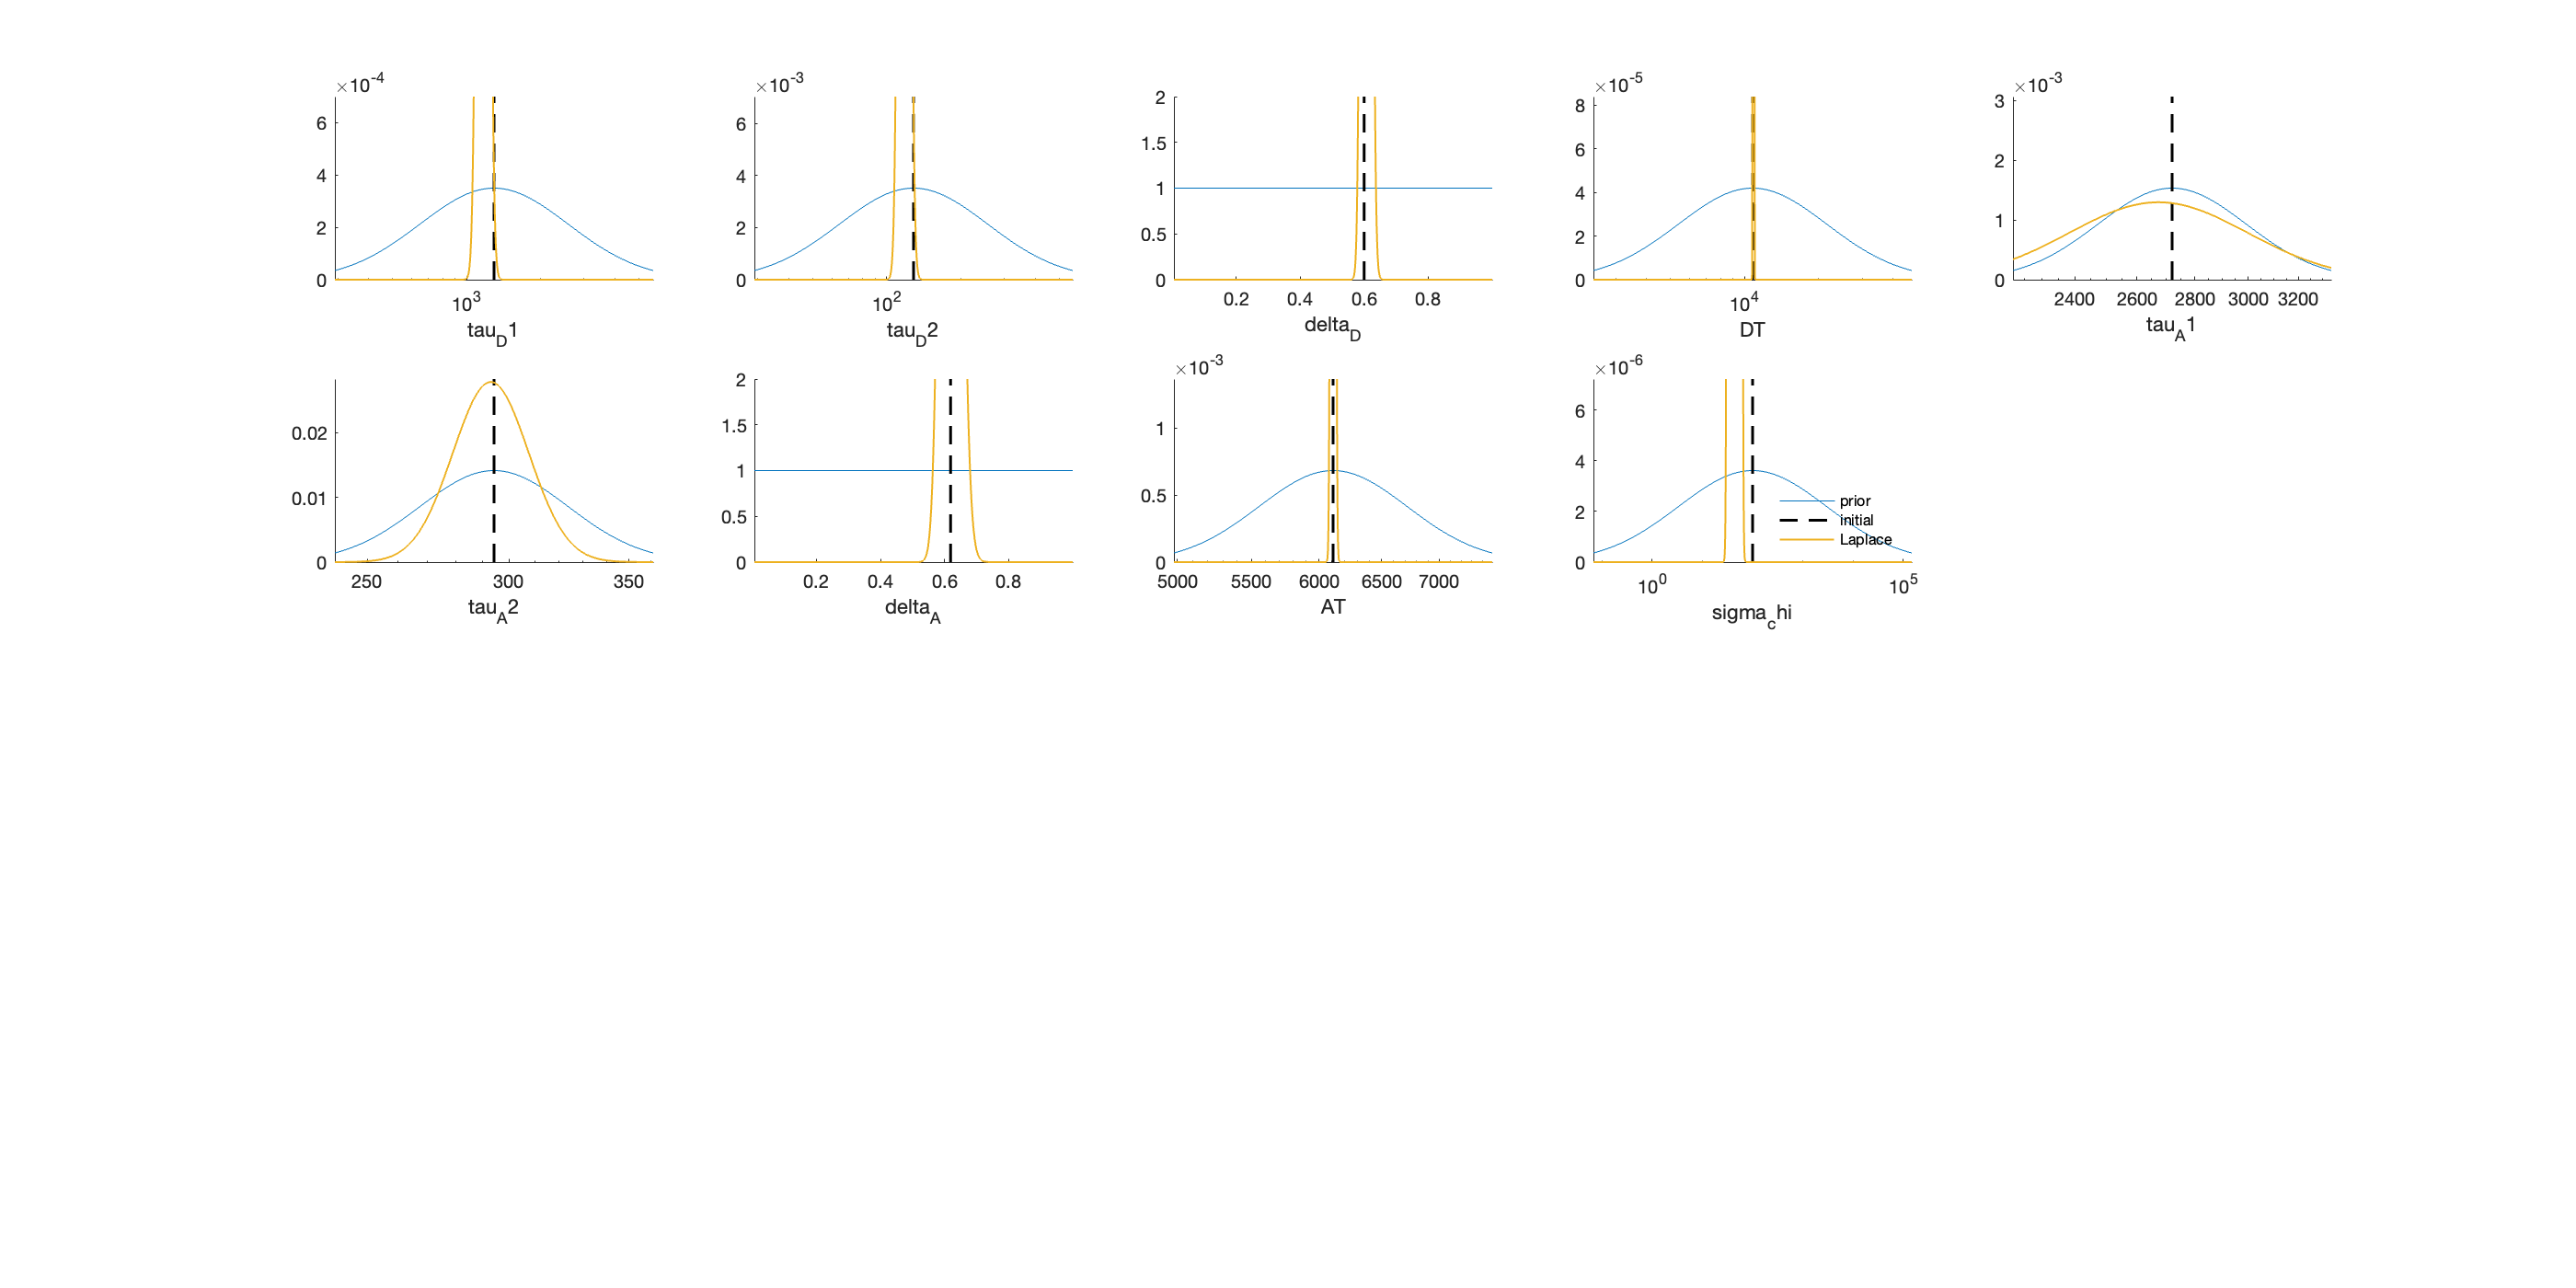

openfig('./posterior_prior_1.fig');
set(gcf,'Visible','on')

This plot shows prior (blue) and posterior (yellow) distributions of the model parameters. Also, the initial rough estimations of the parameter values are shown in dashed lines.  The code generates multiple figures when there are too many panels to fit in a single figure. 

## 5. Interpreting B-FRET results: numerical outputs

All numerical outputs of the B-FRET algorithm are stored in `Bayes_FRET_result.mat`.  

cd(dir0)
cd ./analysis_results/data_1/
load('./Bayes_FRET_result.mat')

The structure array `FRET_sgnl` summarizes statistics of the posterior distributions of the FRET index $E$ as well as the FRET index computed by the E-FRET formula. For example, one can plot the 15.87, 50, and 84.13 perentiles of the posterior distributions of $E$and the E-FRET result:

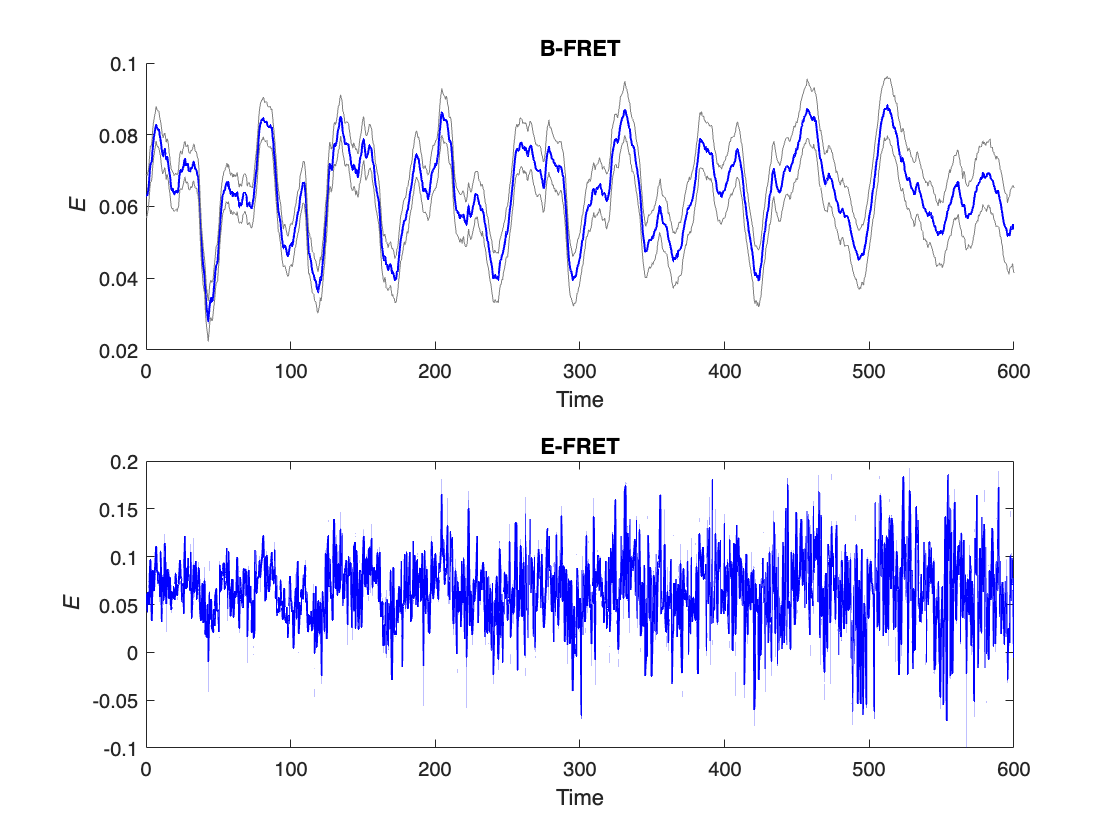

figure;
subplot(2,1,1);hold on;
plot(analyses_results.data.tDD, analyses_results.FRET_sgnl.E_med,'b-','LineWidth',1);
plot(analyses_results.data.tDD, analyses_results.FRET_sgnl.E_15p87,'Color',[0.5 0.5 0.5],'LineWidth',0.5);
plot(analyses_results.data.tDD, analyses_results.FRET_sgnl.E_84p13,'Color',[0.5 0.5 0.5],'LineWidth',0.5);
xlabel('Time');ylabel('\itE');title('B-FRET');

subplot(2,1,2);
plot(analyses_results.data.tDD, analyses_results.FRET_sgnl.Ecorr,'b-','LineWidth',1);
xlabel('Time');ylabel('\itE');title('E-FRET')

Samples drawn from the posterior distributions of $E$ and $\chi \;$are stored in the structure array `state_posterior`. For example, one can plot a trajectory of $E$ drawn from the posterior distribution:  

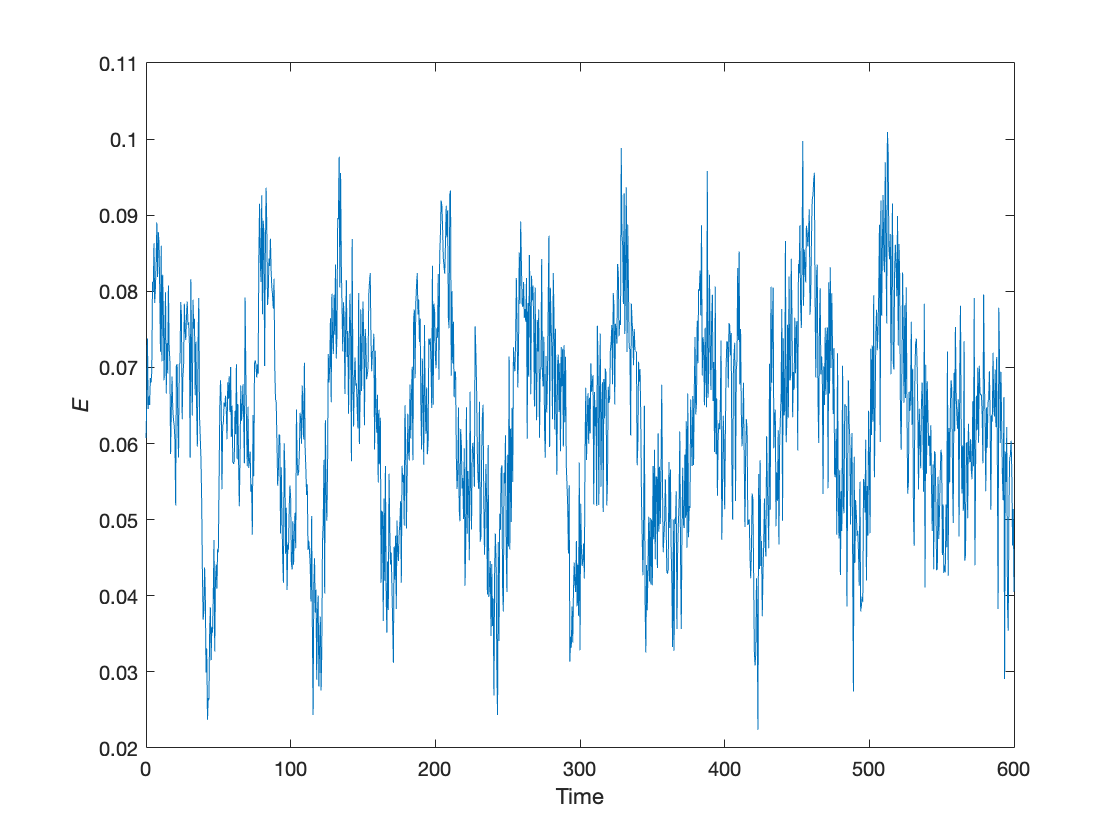

figure;
plot(analyses_results.data.tDD, analyses_results.state_posterior.E(1,:));
xlabel('Time');ylabel('\itE');

By generating large numbers of samples from the posterior distributions of $E$ and $\chi$, one can compute any statistics of these distributions. The numbers of samples are set by `anl_params.Laplace_nsamples (`in `define_analysis_params.m`) when the MCMC sampling method is not used (`anl_params.do_MCMC = 0`) and by anl_params.nsamples when the MCMC sampling method is used (`anl_params.do_MCMC = 1`).   

In the structure arrray `param_posterior`, samples drawn from the posterior distribution of the model parameters are stored as a matrix, `param_posterior.samples`. This matrix size is X (= number of samples set by, e.g., `anl_params.Laplace_nsamples` in `define_analysis_params.m`) by Y (= number of parameters) . Y is organized in the same order as the following:

fields(analyses_results.inputs.prior)

ans = 9×1 cell array
    {'tau_D1'   }
    {'tau_D2'   }
    {'delta_D'  }
    {'DT'       }
    {'tau_A1'   }
    {'tau_A2'   }
    {'delta_A'  }
    {'AT'       }
    {'sigma_chi'}


So, if you wnat to look at the join posterior distributions of DT ($\left\lbrack D_{\mathrm{total}} \right\rbrack$; 4th entry) and AT ($\left\lbrack A_{\mathrm{total}} \right\rbrack$; 8th entry), you can do:

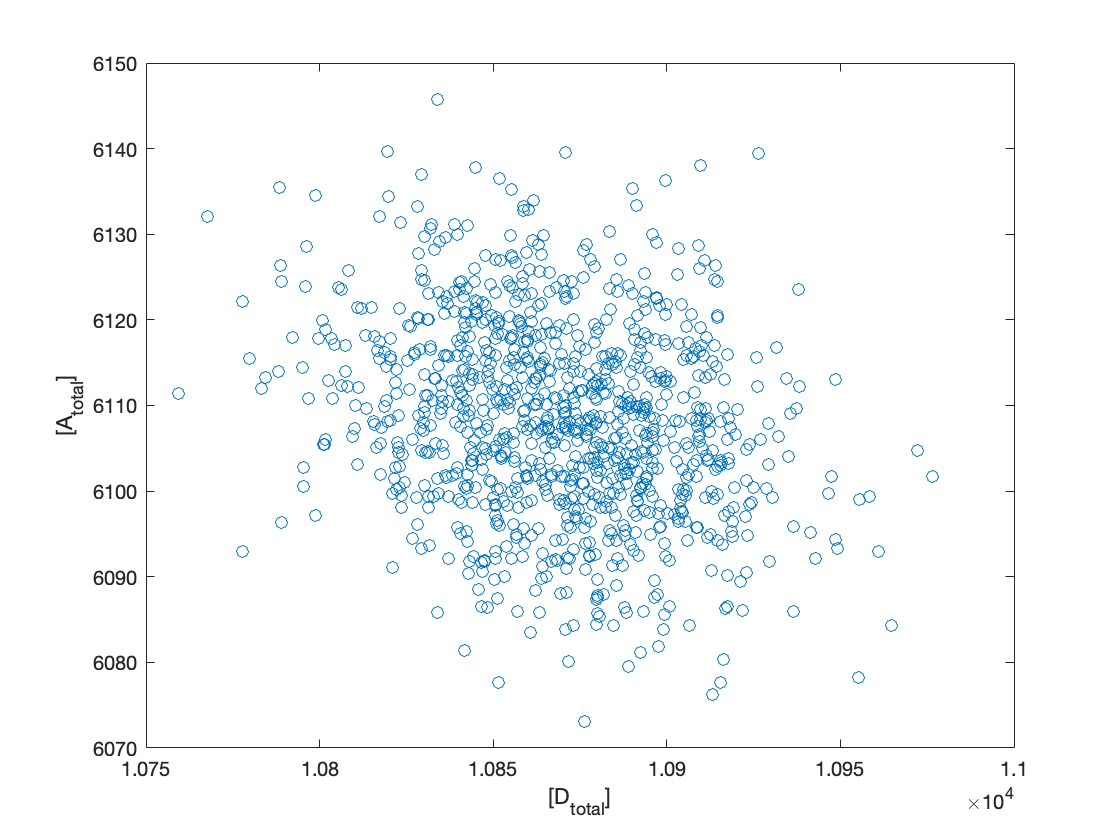

figure;
plot(analyses_results.param_posterior.samples(:,4),analyses_results.param_posterior.samples(:,8),'LineStyle','None','Marker','o');
xlabel('[D_{total}]');ylabel('[A_{total}]');

Other numerical results concerning the posterior distribution of the model parameters are also stored in `param_posterior`. They are:

analyses_results.param_posterior.BIC; % Bayesian information criterion for model selection
analyses_results.param_posterior.log_mu; % Mode of the posterior distribution of log(parameters) (only if anl_params.do_MCMC ~= 1)
analyses_results.param_posterior.mvnsigma; %Variance-covariance matrix of the distribution of log(parameters) (only if anl_params.do_MCMC ~= 1)
analyses_results.param_posterior.nearestSPD; % This is 1, only if the direct numerical estimation of variance-covariance matrix of the Gaussian disribution is replaced with the nearest positive definite matrix. 
analyses_results.param_posterior.p_MAP_vec; %MAP of the parameters (only if anl_params.do_MCMC ~= 1)

Predictions from the learned model about the observables (medians of the smoothing distributions) are stored in `analyses_results.obs_pred`. To compare the actual observables and the predictions of the model, one can do: 

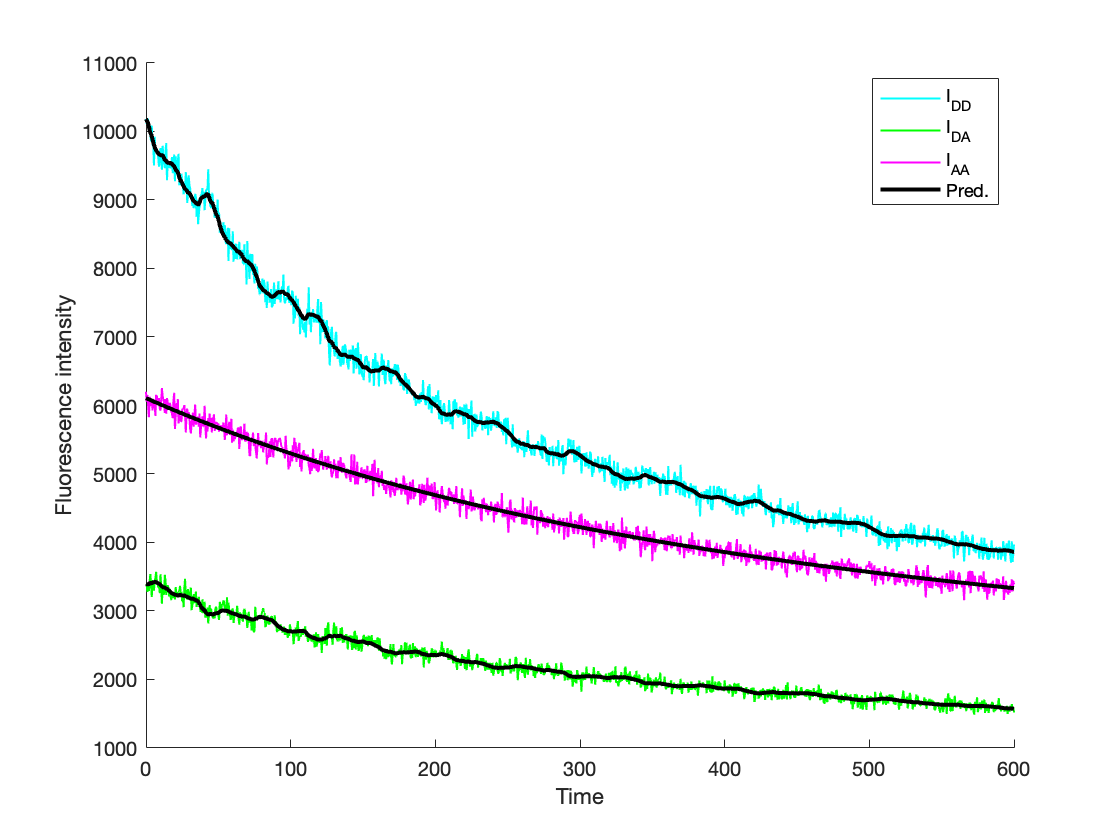

figure; hold on;
l1 = plot(analyses_results.data.tDD,analyses_results.data.IDD(1,:),'c-','LineWidth',1);
l2 = plot(analyses_results.data.tDD,analyses_results.obs_pred.IDD,'k-','LineWidth',2);
l3 = plot(analyses_results.data.tDD,analyses_results.data.IDA(1,:),'g-','LineWidth',1);
plot(analyses_results.data.tDD,analyses_results.obs_pred.IDA,'k-','LineWidth',2);
l4 = plot(analyses_results.data.tAA,analyses_results.data.IAA(1,:),'m-','LineWidth',1);
plot(analyses_results.data.tAA,analyses_results.obs_pred.IAA,'k-','LineWidth',2);
xlabel('Time');ylabel('Fluorescence intensity');
lh = legend([l1, l3, l4, l2],'I_{DD}','I_{DA}','I_{AA}','Pred.');
set(lh,'Location','NorthEast');

## 6. Other data sets

Other than `data_sinusoids.mat` we analyzed above, there are two other data sets `data_steps.mat `and `data_random.mat` in the folder `sample_code/data`. They are both synthetic data and the dynamics of the FRET index $E$ follows step functions and random (Ornstein-Uhlenbeck) process, respectively. They can be analyzed by the B-FRET algorithm in exactly the same way as described above.  